# ACM 11: Week 7 In-class Exercise 3

## Estimate the value of $$\pi$$ with the Monte-Carlo method 

In this exercise we will explore how to the apply the Monte-Carlo sampling method to estimate the numerical value of $$\pi$$.The idea is to sample from a uniform distribution on the square $$[0,1] \times [0,1]$$ by taking many shots, count the number of shots inside the quarter circle, and then divide by the total number of shots. The law of large numbers will tell us that eventually this probability will converge to the ratio between the area of the quarter circle and the area of the square. Given that this ratio is equal to four times the area of a circle with radius 1, we only need to compute the hit ratio and multiply it by 4 to get an estimate of $$\pi$$.

**In-class activity: write your answers below each prompt and upload to Canvas when you are done (one upload per group is fine)**

**(0)  Group names: **

**Kyle McGraw, Dallas Taylor**

**(1) Let's firstly visualize the sampling process. Change the number of sample points **$$N$$** using the drop-down menu and observe how the visualization behaves differently. Note that points falling inside the quarter circle are colored blue, while points falling outside the quarter circle are colored red. Make sure you understand what this code is doing and ask questions about parts that are confusing.**

The code block below performs the sampling process:

close all 
clear; clc;

% Randomly sample sufficiently many datapoints
x = rand(1e5,1);    % these are random values in [0, 1] uniformly distributed
y = rand(1e5,1);    % same as above

% Compute indicator function on the quarter circle for all of the above
% random points
indicator = (x.^2+y.^2<1);

N = 10000 % take just the first N samples for visualization (10 million points is a lot for plotting)

N = 10000

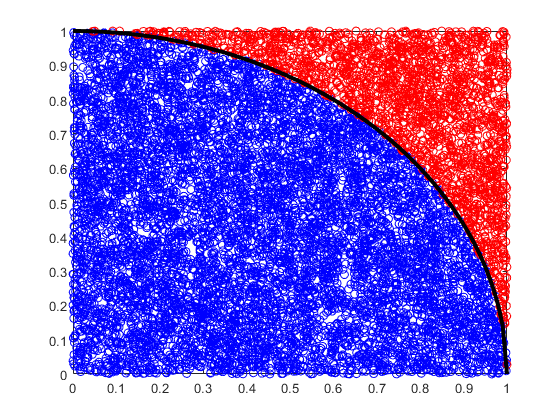

ind = find(indicator(1:N) ==1); % this yields the indices of x and y for which indicator = 1
nind = find(indicator(1:N)==0); % this yields the indices of x and y for which indicator = 0

figure(1);
plot(x(ind),y(ind),'bo') ; hold on  % Scatter plot of random points within the circle, colored blue
plot(x(nind),y(nind),'ro');         % Scatter plot of random points outside the circle, colored red

% Plot circle boundary for visualization
xcirc = 0:0.01:1;
ycirc = sqrt(1-xcirc.^2);
plot(xcirc,ycirc,'-k','linewidth',3);
hold off

**(2) Now we will use Monte Carlo to estimate the value of **$\pi$. The proportion of randomly sampled points in the unit square is an estimator for the quantity

$\frac{\textrm{Area}\;\textrm{of}\;\textrm{quarter}\;\textrm{circle}}{\textrm{Area}\;\textrm{of}\;\textrm{unit}\;\textrm{square}}=\frac{\pi }{4}$.

Thus, we can estimate $\pi$ as follows:

$\pi \approx 4\cdot \;\frac{#\;\textrm{points}\;\textrm{in}\;\textrm{the}\;\textrm{circle}}{\textrm{total}\;#\;\textrm{points}}$.

In the code block below, we compute an example of using the first 1000 random points to estimate $\pi$. If you run this script a few times you should see it take on random values that are close to the true value of $\pi$. 

Your job: use the above samples to compute the *cumulative* estimate of $\pi$. This means you should end up with an $N\times 1$ vector whose $n$-th entry is the estimate of $\pi$ computed using the first $n$ samples (`cumsum` is a useful function for this). 

We have included a figure that plots the expected rate of error decay ($1/\sqrt{N}$) using a loglog axis. For your cumulative estimate, use loglog to plot the absolute value of the error (with respect to the true value of $\pi$) on the same axis. Run it a few times - do you think your plots are consistent with the expected error decay rate?

The plots look pretty consistent with the expected error decay rate.

example_estimate = 4*sum(indicator(1:1000))/1000

example_estimate = 3.1160

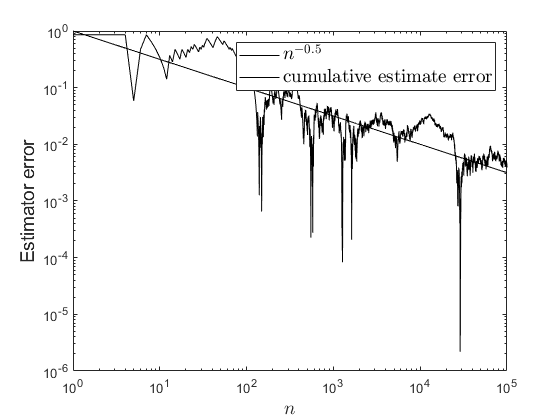


n = (1:1e5)';
pi_est = 4*cumsum(indicator)./n; % Calculate cumulative estimate

figure(2);
loglog(1./sqrt(n),'k'); hold on
loglog(abs(pi_est-pi),'k');
legend({'$n^{-0.5}$','cumulative estimate error'},'interpreter','latex','fontsize',14)
xlabel('$n$','interpreter','latex','fontsize',14)
ylabel('Estimator error','fontsize',14)